s = tf('s');
G_s = (2 * (1 - s))/ ((3 * s + 1) * (s + 1))

G_s =
 
     -2 s + 2
  ---------------
  3 s^2 + 4 s + 1
 
Continuous-time transfer function.
Model Properties


sampling period

Ts = 0.5; 


Discretization methods to compare

'zoh': zero-order hold

'foh': first-order hold

'tustin': bilinear

'matched': matched pole-zero

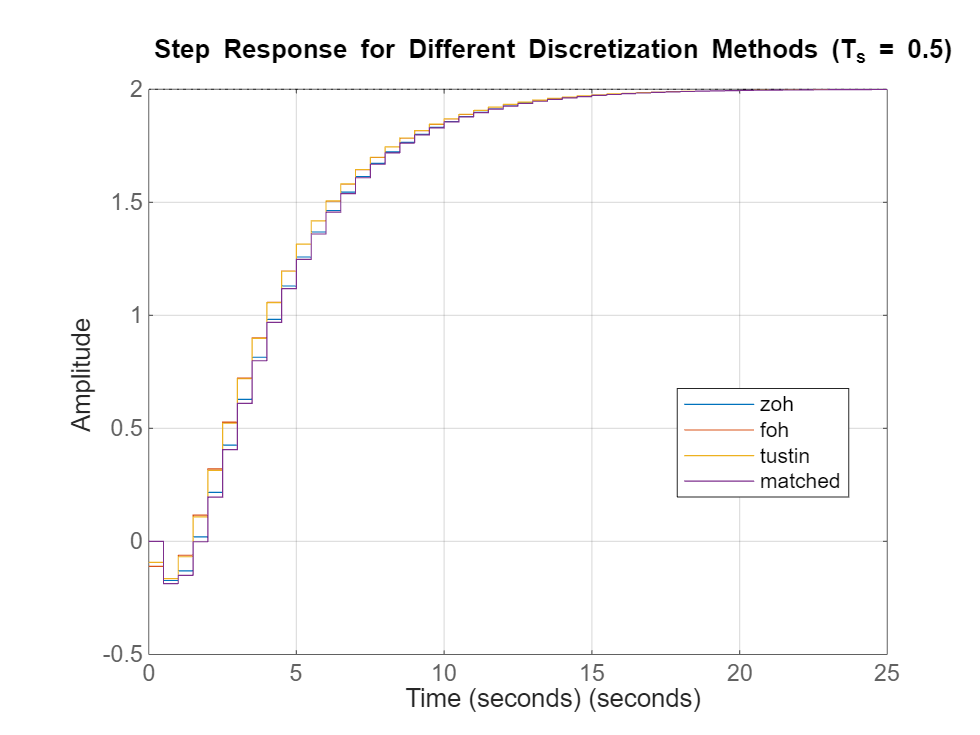

methods = {'zoh', 'foh', 'tustin', 'matched'}; 

figure;
hold on;

for i = 1:length(methods)
    method = methods{i}; 
    G_z = c2d(G_s, Ts, method);
    step(G_z);

    % disp(['Discrete transfer function for method: ' method]);
    % disp(G_z);
end

legend(methods, 'Location', 'Best');
title(['Step Response for Different Discretization Methods (T_s = ' num2str(Ts) ')']);
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;
hold off;